## Introduction

#### What is the main theme? Why is it important?

The purpose of this project is to study the impact of climate on glaciers through modeling the kinematics and mechanics of ice flow. It is important because glaciers are sensitive to slight changes in climate. We can infer past climate based on how glaciers molded landscapes and changed vegetation over time. To understand these changes, we need to understand how glaciers respond to changes in climate.

#### What observations, models, etc are used by others that are different from what you are doing in the project?

## Equations

#### What are the fundamental physical/chemical/etc. processes? 

This model is based on the concept that a glacier is a one-dimensional flow system which is continuously receiving or losing new material. **More glacier info??** We are modeling a kinematic wave equation as it pertains to ice flow. A wave in this sense refers to a point carrying a specified property (q) moving through a medium at a speed different than the medium itself.

#### Relevant equations and potentially where they come from (i.e. how are they derived)

Kinematic wave equation (eqn 4 in Nye 1960)

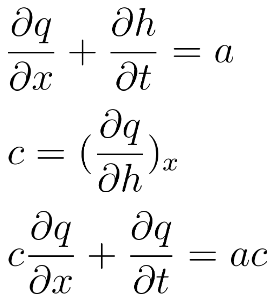

#### Describe all terms and parameters. 

q = volume of ice passing a given point in unit time (1 / unit breadth)

a = accumulation rate at surface (positive = addition of ice due to snowfall or avalanche, negative = melting or evaporation of ice)

c = velocity (but not velocity of the ice itself, which is u = q/h)

#### Describe any assumptions being made

We assume the volume and velocity (c) of the glacier are constant. Some simulations run assume accumulation is constant, and some assume accumulation oscillates a sine function throughout the year.

## Numerical Methods

#### Describe the numerical methods used.

Forward Euler

#### Why did you choose to use these methods

% Forward Euler

v = 1; %m/s
tf = 3.154e+7; %seconds
n = 2000;
dx = 2000;
x = linspace(0 , 2000000, n);
Cor = 1;
dt = Cor*(dx)/v;
nt = ceil(tf/dt);


a = sin(2*pi*x);
Q_t0 = sin(2*pi*x) ;

Q = nan(n,nt);

Q(:,1) = Q_t0;

M = spdiags([Cor.*ones(n,1),1-Cor.*ones(n,1)],-1:0,n,n);% can i use this same matrix stucture

M(1,1) = 1;
M(1,2) = 0;
M(2,1) = 1;
M(2,2) = 1-Cor;

%boundary

for k = 1:nt-1
    Q(:,k+1) = M*Q(:,k)-a.*v.*dt;
end

Unable to perform assignment because the size of the left side is 2000-by-1 and the size of the right side is 2000-by-2000.

out = 'done'
figure
plot(x,Q(:,1:86400/dt:end))
xlabel('Accumulation')
ylabel('Volume of Ice')
title('Advection using C = 1')
legend

## Results

#### What simulations did you run with the model?

Changed accumulation from constant to sin function (seasonal changes)

#### Describe the results.

#### How do the results compare with any known solutions, or data?

#### How do the results change with different methods, time steps, grid spacing, or model parameters?

#### What did the model tell you about the process you were studying?

#### How could the model be improved in terms of methods used or processes included?